clc
clear
x_torso = 0.12;
z_robot = 0.78;
swingHeight = 0.1;
delta_z_vrp = 0.68;
step_length = 0.25;
g = 9.807; 
sample_time = 0.01;
is_left = true;
num_steps = 5;
t_step = .8;
t_ds = .3;
alpha = .5;
t_ss = t_step - t_ds;
t = 0:sample_time:t_step*(num_steps+2) - sample_time;

if is_left
    foot_plants = [0 x_torso 0; 0 -x_torso 0];
    for i=3:num_steps+3
        foot_plants(i, :) = [(i-2)*step_length (-1)^(i-1)*x_torso 0];
    end
else
    foot_plants = [0 -x_torso 0; 0 x_torso 0];
    for i=3:num_steps+3
        foot_plants(i, :) = [(i-2)*step_length (-1)^(i)*x_torso 0];
    end
end
foot_plants(end+1, :) = [1,-1, 1] .* foot_plants(end,:);

r_vrpd = foot_plants(2:end-1, :) + [0 0 delta_z_vrp];
r_vrpd(end+1, :) = [1, 0, 1] .* r_vrpd(end, :);

DCM Trajectory Generation

ksi_d_eos = zeros(num_steps+2,3);
ksi_d_eos(num_steps+2,:) =  r_vrpd (end,:);
for i=num_steps+1:-1:1
    ksi_d_eos(i,:) = r_vrpd(i+1,:) + (exp((-sqrt(g/delta_z_vrp)*t_step)))*(ksi_d_eos(i+1,:)-r_vrpd(i+1,:));
end 
figure()
scatter3(ksi_d_eos(:,1),ksi_d_eos(:,2),ksi_d_eos(:,3),'b')
hold on
ksi_d = zeros(length(t), 3);

for j = 1:length(t)
    step_num = ceil(j*sample_time/t_step);
    local_t=mod(t(j),t_step);
    ksi_d(j,:) = r_vrpd(step_num,:) + exp(sqrt(g / delta_z_vrp)*(local_t - t_step)).*(ksi_d_eos(step_num, :) - r_vrpd(step_num, :));
end
plot3(ksi_d(:,1),ksi_d(:,2),ksi_d(:,3))


Double Support Inital & Final Points

for i = 1:num_steps+2
    if i==1
        ksi_iniDS(i,:) = ksi_d(i,:);
        ksi_eoDS(i,:) = r_vrpd(i,:) + exp(sqrt(g/delta_z_vrp)*t_ds*(1-alpha))*(ksi_d(i,:)-r_vrpd(i,:));
        ksi_dot_iniDS(i,:) = (ksi_iniDS(i,:) - r_vrpd(i,:))*sqrt(g/delta_z_vrp);
        ksi_dot_eoDS(i,:) = (ksi_eoDS(i,:) - r_vrpd(i,:))*sqrt(g/delta_z_vrp);
    else
        ksi_eoDS(i,:) = r_vrpd(i,:) + exp(sqrt(g/delta_z_vrp)*t_ds*(1-alpha))*(ksi_d_eos(i-1,:)-r_vrpd(i,:));
        ksi_iniDS(i,:) = r_vrpd(i-1,:) + exp(-sqrt(g/delta_z_vrp)*t_ds*alpha)*(ksi_d_eos(i-1,:)-r_vrpd(i-1,:));
        ksi_dot_iniDS(i,:) = (ksi_iniDS(i,:) - r_vrpd(i-1,:))*sqrt(g/delta_z_vrp);
        ksi_dot_eoDS(i,:) = (ksi_eoDS(i,:) - r_vrpd(i,:))*sqrt(g/delta_z_vrp);
    end
end
scatter3(ksi_eoDS(:,1),ksi_eoDS(:,2),ksi_eoDS(:,3),'y','filled');
hold on
scatter3(ksi_iniDS(:,1),ksi_iniDS(:,2),ksi_iniDS(:,3),'k','filled');

Double Support Trajectory

traj_ds = struct('index', {}, 'ksi_ds', {}, 'state', {});

for i=1:num_steps + 2
    wpts=[ksi_iniDS(i,1) ksi_eoDS(i,1);ksi_iniDS(i,2) ksi_eoDS(i,2); ksi_iniDS(i,3) ksi_eoDS(i,3)];
    velpts = [ksi_dot_iniDS(i,1) ksi_dot_eoDS(i,1);ksi_dot_iniDS(i,2) ksi_dot_eoDS(i,3);ksi_dot_iniDS(i,3) ksi_dot_eoDS(i,3)];
    if i == 1

        tpts=[0 (1-alpha) * t_ds - sample_time];
        tvec=tpts(1):sample_time:tpts(end);
        traj_ds(i).index = i;
        [q, qd, qdd, pp] = cubicpolytraj(wpts, tpts, tvec,'VelocityBoundaryCondition',velpts);
        traj_ds(i).ksi_ds = q';
    else
        
        tpts=[0 t_ds - sample_time];
        tvec=tpts(1):sample_time:tpts(end);
        traj_ds(i).index = i;
        [q, qd, qdd, pp] = cubicpolytraj(wpts, tpts, tvec,'VelocityBoundaryCondition',velpts);
        traj_ds(i).ksi_ds = q';
    end
    plot3(q(1, :), q(2, :), q(3, :))
end 


Merging Trajectories

final_ksi_traj = ksi_d;
final_ksi_traj(1:(t_ds * (1-alpha)) / sample_time, :) = traj_ds(1).ksi_ds;
for i=1:num_steps+1
    initial_ds = floor((i * t_step - alpha * t_ds) / sample_time);
    final_ds = floor((i * t_step + (1 - alpha) * t_ds) / sample_time)-1;
    final_ksi_traj(initial_ds:final_ds, :) = traj_ds(i+1).ksi_ds;
end

COM Trajectory

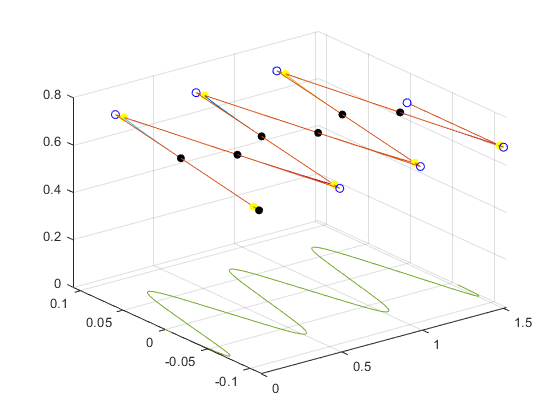

t_s = 0:sample_time:t_step * 7 - sample_time;
com_traj_final(1,:)=[0,0,delta_z_vrp];
com_dot = [0, 0, 0];
for index = 2:length(t)
    xx = 0;
    for t =1:index
        inte =sample_time*final_ksi_traj(t,:)* exp((t*sample_time)/sqrt(delta_z_vrp/g));
        xx = inte + xx;
    end
    com_traj_final(index,:) = (xx/(sqrt(delta_z_vrp/g)) + com_traj_final(1,:))*exp((-index*sample_time)/sqrt(delta_z_vrp/g));
    com_dot(index, :) = sqrt(g/delta_z_vrp) * (final_ksi_traj(index,:) - com_traj_final(index,:));
end
plot(com_traj_final(:,1),com_traj_final(:,2));

Single Support DCM & COM Trajectory Separation

traj_ss = struct('index', {}, 'ksi_ss', {}, 'state', {});
traj_ss(1).index = 1;
traj_ss(1).ksi_ss = ksi_d(((1-alpha)*t_ds)/sample_time + 1:(t_step - alpha*t_ds)/sample_time, :);
traj_ss(1).state = com_traj_final(((1-alpha)*t_ds)/sample_time + 1:(t_step - alpha*t_ds)/sample_time, :);
traj_ss(1).state_dot = com_dot(((1-alpha)*t_ds)/sample_time + 1:(t_step - alpha*t_ds)/sample_time, :);
for i=1:num_steps+1
    init_ss = floor(((i) * t_step + (1 - alpha) * t_ds) / sample_time) + 1;
    final_ss = floor(((i+1) * t_step - alpha * t_ds) / sample_time);
    traj_ss(i+1).index = i+1;
    traj_ss(i+1).ksi_ss = ksi_d(init_ss:final_ss, :);
    traj_ss(i+1).state = com_traj_final(init_ss:final_ss, :);
    traj_ss(i+1).state_dot = com_dot(init_ss:final_ss, :);
    
end

Double Support COM Trajectory Separation

traj_ds(1).state = com_traj_final(1:((1 - alpha) * t_ds) / sample_time, :);
traj_ds(1).state_dot = com_dot(1:((1 - alpha) * t_ds) / sample_time, :);

for i=1:num_steps+1
    init_ds = floor((i * t_step - alpha * t_ds) / sample_time);
    final_ds = floor((i * t_step + (1 - alpha) * t_ds) / sample_time)-1;
    traj_ds(i+1).state = com_traj_final(init_ds:final_ds, :);
    traj_ds(i+1).state_dot = com_dot(init_ds:final_ds, :);
    
end

Steps Information Cell

stepinfos = cell(1,num_steps+1);

Decreasing Robot's Height

walkRdyPoints = [0      0; 
                 0      0; 
                 z_robot delta_z_vrp];  
timepoints = [0 0.5];
timevec = timepoints(1):sample_time:timepoints(end)-sample_time; 
[q, qd] = cubicpolytraj(walkRdyPoints, timepoints, timevec); 

% save data
stepinfo.index = 1; 
bodystate = [q(1,:); qd(1,:); q(2,:); qd(2,:); q(3,:); qd(3,:)]; % pos wrt world   
stepinfo.state = bodystate;
stepinfo.timevec = timevec; 
stepinfo.mode = 'doublesupport'; 
if is_left
    stepinfo.footposeleft = foot_plants(1,:)';
    stepinfo.footposeright = foot_plants(2,:)';
else
    stepinfo.footposeright = foot_plants(1,:)';
    stepinfo.footposeleft = foot_plants(2,:)';
end
stepinfo.footplant = foot_plants(1, :)';
stepinfos{1} = stepinfo;

Saving SS & DS Trajectory into stepinfos


for i=1:num_steps+2
    % double support
    stepinfo = struct;
    init_time = timevec(end) + sample_time;
    final_time = init_time + t_ds - sample_time;
    if i == 1
        final_time = init_time + t_ds * (1-alpha) - sample_time;
    end
    timevec = init_time:sample_time:final_time;
    stepinfo.index = 2 * i;
    stepinfo.timevec = timevec;
    stepinfo.mode = 'doublesupport';
    stepinfo.footplant = foot_plants(i + 1,:)';
    if rem(i,2) > 0
        stepinfo.footposeright = foot_plants(i+1,:)';
        stepinfo.footposeleft = foot_plants(i,:)';
    else
        stepinfo.footposeleft = foot_plants(i+1,:)';
        stepinfo.footposeright = foot_plants(i,:)';
    end
    stepinfo.ksi = traj_ds(i).ksi_ds;
    stepinfo.state([1,3,5], :) = traj_ds(i).state';
    stepinfo.state([2,4,6], :) = traj_ds(i).state_dot';
    stepinfos{2 * i} = stepinfo;
    % single support
    stepinfo = struct;
    init_time = timevec(end) + sample_time;
    final_time = init_time + t_ss - sample_time;
    timevec = init_time:sample_time:final_time;
    stepinfo.index = 2 * i + 1;
    stepinfo.timevec = timevec;
    stepinfo.footplant = foot_plants(i + 1,:)';
    if is_left
        if rem(i,2) > 0
            stepinfo.mode = 'singlesupportright';
            stepinfo.footposeright = foot_plants(i+1,:)';
        else
            stepinfo.mode = 'singlesupportleft';
            stepinfo.footposeleft = foot_plants(i+1,:)';
        end   
    else
        if rem(i,2) > 0
            stepinfo.mode = 'singlesupportleft';
            stepinfo.footposeleft = foot_plants(i+1,:)';
        else
            stepinfo.mode = 'singlesupportright';
            stepinfo.footposeright = foot_plants(i+1,:)';
        end   
    end
    stepinfo.ksi = traj_ss(i).ksi_ss;
    stepinfo.state([1,3,5], :) = traj_ss(i).state';
    stepinfo.state([2,4,6], :) = traj_ss(i).state_dot';
    swingfootpos0 = foot_plants(i, :);
    swingfootpos1 = foot_plants(i+2, :);
    [qswing, dqswing, ddqswing] = getSwingFootTraj(swingfootpos0', swingfootpos1', swingHeight, ...
                                init_time, final_time,sample_time);
    stepinfo.swing([1, 3, 5], :) = qswing;
    stepinfo.swing([2, 4, 6], :) = dqswing;
    stepinfos{2 * i + 1} = stepinfo;
end